% Sample program to process your data for post-lab
%%%%% Make sure to modify as required %%%%%%
close all
clear all
clc

## Prefined Parameters get these values during the experiment

r = 0.2159; %Length of the pendulum (m)
g = -9.81; %Constant gravity (m/s^2)

## Start user required information Reading data from the file 3 column data

fid = fopen('../Data/Student_Name_Expt_03.dat');
linel = fgetl(fid);
data = fscanf(fid, '%f \t %f \t %f \n', [3 inf]);

## Storing data in the right variables

t = data(1,:); % Time data
y1 = data(2,:); % Angular location (degree)
y2 = data(3,:); % Accelerometer data (m/s^2)
fclose(fid);

## Converting degrees to radian

rad = y1*pi/180; % convert degree value to radians

## Performing numerical differentiation - dx/dt to get angular velocity

theta_d =  diff(rad) ./ diff(t); % calculating angular velocity rad/s

## Calculating acceleration from two different methods

acc_1 =  - (theta_d.^2) * r; % calculated acceleration m/s^2
acc_2 = y2 - (g*cos(rad)); % removing acceleration due to gravity component accelerometer data

## Generating figure with specific size

figure (1)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data

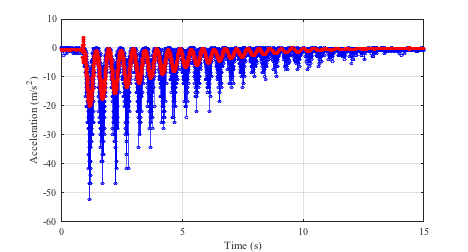

plot(t(1:end-1),acc_1,'-bo','markersize',3);hold on
plot(t,acc_2,'ro','markersize',3,'markerfacecolor','r');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
grid on


ylim([-70 10])
xlim([0 15])

legend('Expt. data','Accelerometer data','location','Southeast')
title('FirstName LastName''s Name Plot')

## Saving the files in png and pdf format

figName = ('../Figures/Student_Name_Expt03_Postprocess');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf, 'Position');
set(gcf, 'PaperSize', figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')